## **Investigate 15 MW turbine properties**

load("bladedata_IEA_15MW.mat");

### **Plot chord and twist**

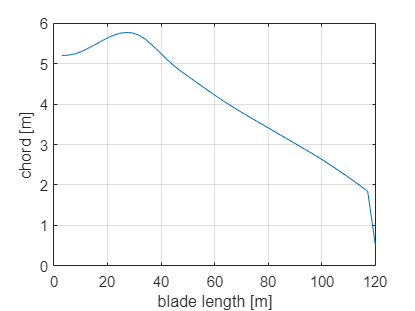

clf
plot(bladedata.radius,bladedata.chord)
xlabel("blade length [m]");
ylabel("chord [m]")
grid on

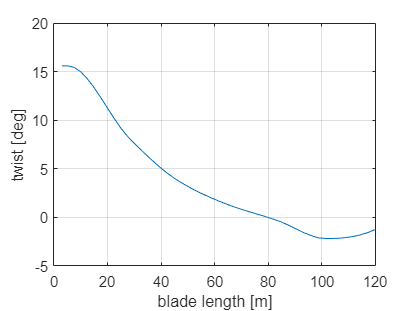


plot(bladedata.radius,bladedata.twist)
xlabel("blade length [m]");
ylabel("twist [deg]")
grid on

### Plot lift and drag coefficents

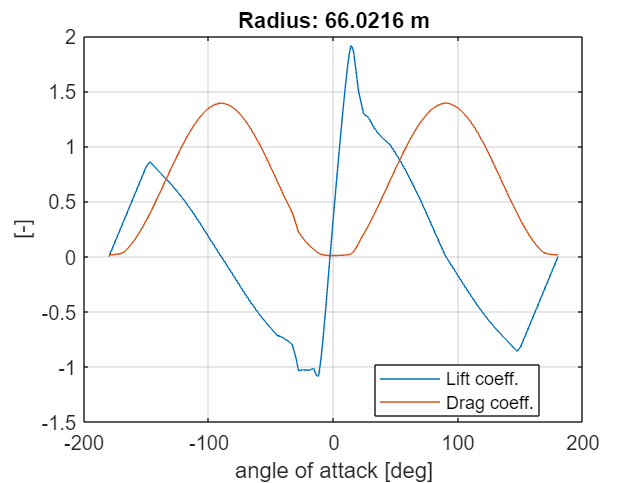

section=27;
clf
plot(bladedata.airfoil(:,1,section),bladedata.airfoil(:,2,section))
hold on
plot(bladedata.airfoil(:,1,section),bladedata.airfoil(:,3,section))
xlabel("angle of attack [deg]");
ylabel("[-]");
title(['Radius: ' num2str(bladedata.radius(section)) ' m'])
legend(["Lift coeff.","Drag coeff."],Location="best");
grid on
hold off